clearvars

## Config

mapSize.scale = 50;
mapSize.placingResolution = 100;
mapSize.x = round(26.5*mapSize.scale);
mapSize.y = round(13.5*mapSize.scale);

## Map Parse with Laser

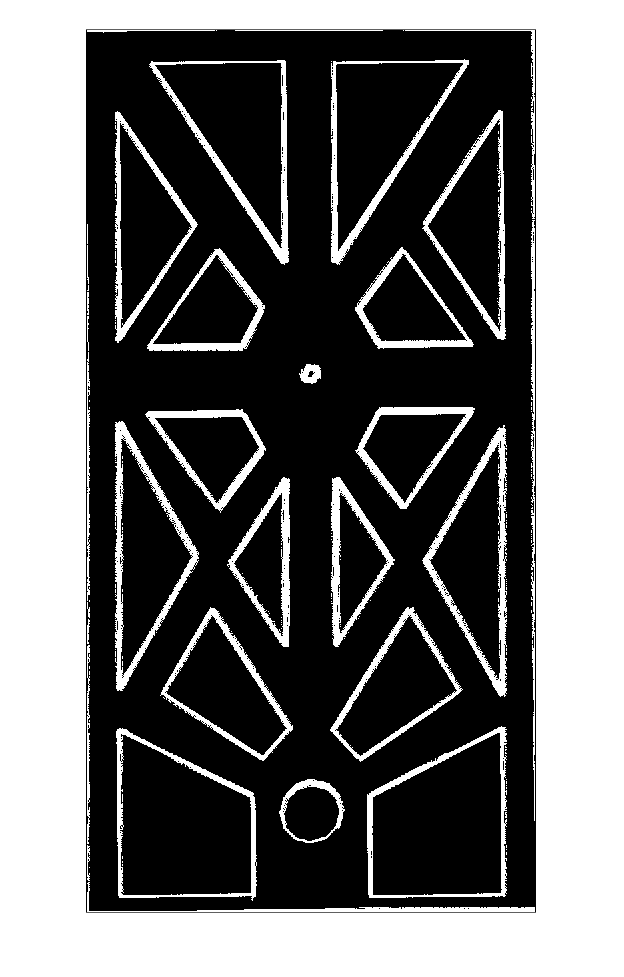

BW = zeros(mapSize.x,mapSize.y);
robotName = 'Marvin';
laserName = 'LMS100';

for x = 1:mapSize.x
    for y = 1:mapSize.y
        if 0 == mod(x,mapSize.placingResolution)
            % Front
            apoloPlaceMRobot(robotName, [x/mapSize.scale,y/mapSize.scale,0], 0);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            for i = 1:length(ld)
                angl = (i/length(ld))*3*pi/2 - 3*pi/4;
                dist = ld(i);
                if dist < 10
                    % Rellenamos un pixel encontrado
                    indx = min([mapSize.x-1,max([2,     round(x+cos(angl)*dist*mapSize.scale)])]);
                    indy = min([mapSize.y-1,max([2,     round(y+sin(angl)*dist*mapSize.scale)])]);
                    BW(indx,indy) = 255;
                end
            end
            pause(0.001)
            % Back
            apoloPlaceMRobot(robotName, [x/mapSize.scale,y/mapSize.scale,0], pi);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            for i = 1:length(ld)
                angl = (i/length(ld))*3*pi/2 - 3*pi/4 -pi;
                dist = ld(i);
                if dist < 10
                    % Rellenamos un pixel encontrado
                    indx = min([mapSize.x-1,max([2,     round(x+cos(angl)*dist*mapSize.scale)])]);
                    indy = min([mapSize.y-1,max([2,     round(y+sin(angl)*dist*mapSize.scale)])]);
                    BW(indx,indy) = 255;
                end
            end
            pause(0.001)
        end
    end
end

imshow(BW)

mapRaw = BW;
save('jardinBinMapParsed.mat',"BW");

## Processing

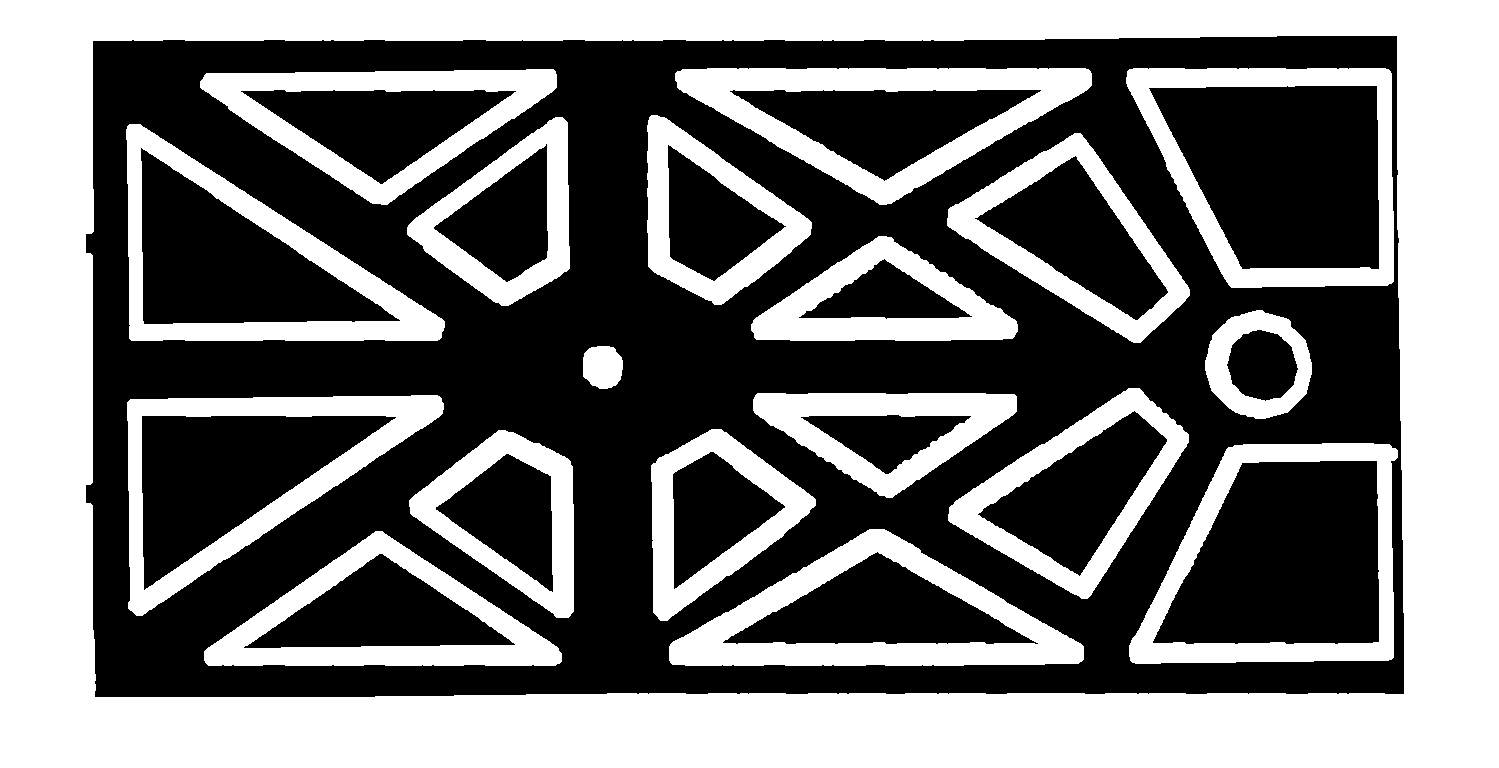

se = offsetstrel('ball',4,4);
BW = imdilate(mapRaw,se);
BW = imerode(BW,se);
BW = imrotate(BW,90);
BW = imbinarize(BW);
mapProcessed = BW;

imshow(BW)

% save('jardinBinMapCorrectAndDilated.mat',"BW");

## Add Fountain

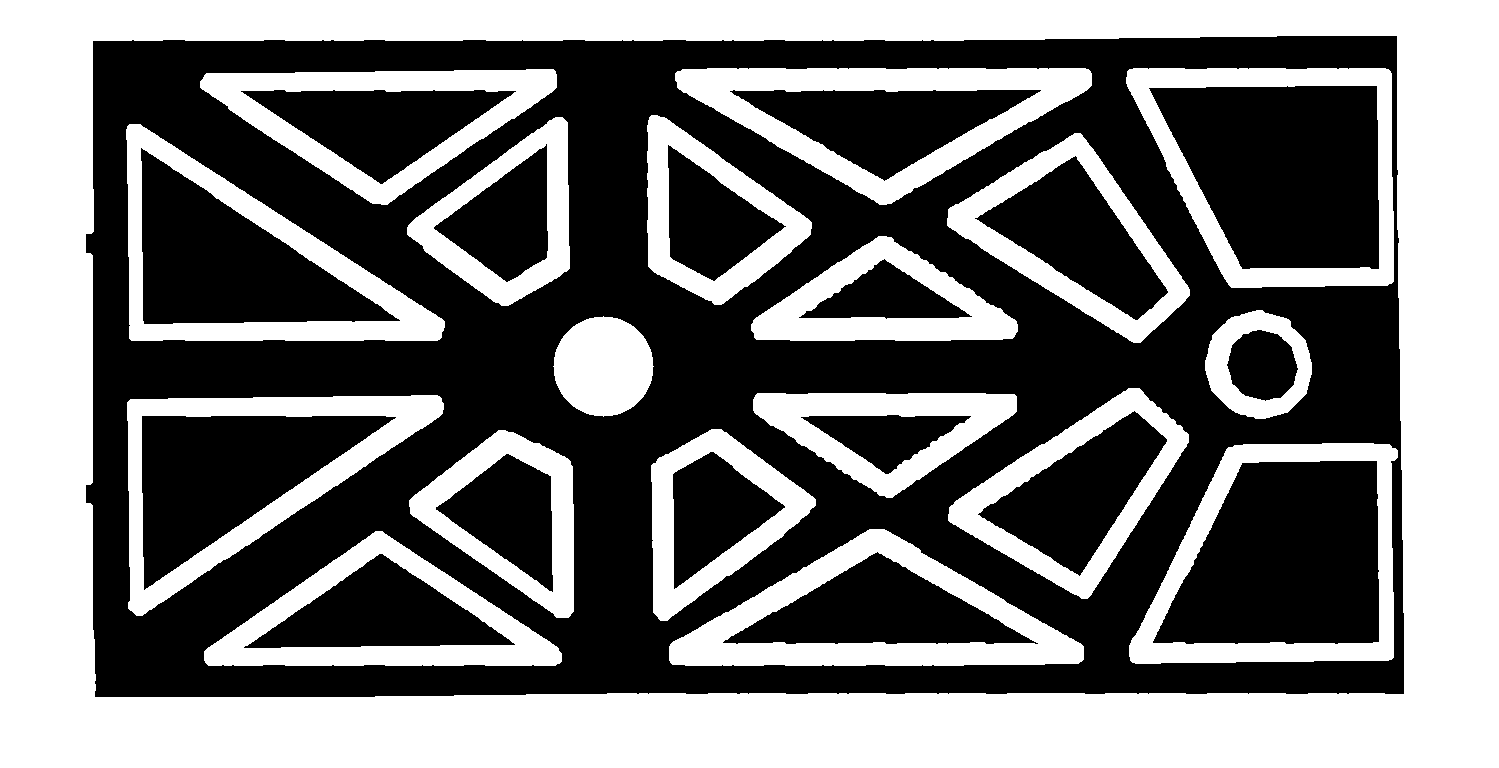

fountain.center = [ round(10.35 * mapSize.scale),...
                    round(6.75  * mapSize.scale)        ];
fountain.radius = round(1.0 * mapSize.scale);

% Create the image.
[columnsInImage, rowsInImage] = meshgrid(1:mapSize.x, 1:mapSize.y);
% Create the circle in the image.
circlePixels = (rowsInImage - fountain.center(2)).^2 ...
    + (columnsInImage - fountain.center(1)).^2 <= fountain.radius.^2;

BW = BW | circlePixels;
imshow(BW)

mapFountain = BW;
% save('jardinBinMapCorrectAndDilated.mat',"BW");

## Save

BW = mapRaw;
save('jardinBinMapParsed.mat',"BW");
BW = mapProcessed;
save('jardinBinMapCorrectAndDilated.mat',"BW");
BW = mapFountain;
save('jardinBinMapWithFountain.mat',"BW");